clc

Matilde_13_09_2023_AM = 460×6 table
         timestamp         altitude    cadence    distance    speed     power
    ___________________    ________    _______    ________    ______    _____

    2023-09-13T10:41:11       1460       NaN       30378      13.133       0 
    2023-09-13T10:41:12       1460       NaN       30384       18.81       0 
    2023-09-13T10:41:13       1460        37       30389      20.491      67 
    2023-09-13T10:41:14       1460        43       30395      21.229     111 
    2023-09-13T10:41:15     1460.2        46       30401      22.338     160 
    2023-09-13T10:41:16     1460.2        46       30408      23.681     170 
    2023-09-13T10:41:17     1460.4        48       30415      24.455     170 
    2023-09-13T10:41:18     1460.4        51       30422 

clear all

## Run Comparator

In case you need to compare 2 runs, you can use this code. Simply select 2 runs to compare by using the selectors down here and let the code work. It plots:

- Speed;

- Power;

- Cadence;

- Average Power input;

- Max speed reached.

The file format is always the same, so the columns area always in the correct order.

speed_1 = table2array(run_1(:,5));
speed_2 = table2array(run_2(:,5));

power_1 = table2array(run_1(:,6));
power_2 = table2array(run_2(:,6));

cadence_1 = table2array(run_1(:,3));
cadence_2 = table2array(run_2(:,3));

time_1 = (1:size(power_1))';
time_2 = (1:size(power_2))';

avg_power1 = mean(power_1)

avg_power1 = 107.0087

avg_power2 = mean(power_2)

avg_power2 = 128.1461


max_v_1 = max(speed_1)

max_v_1 = 75.1430

max_v_2 = max(speed_2)

max_v_2 = 93.3480

## Data Visualization

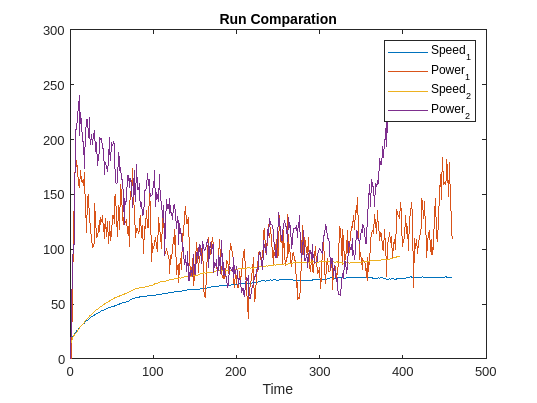

figure
plot(time_1,speed_1,time_1,power_1);
title("Run Comparation");
xlabel("Time");
hold on
plot(time_2,speed_2,time_2,power_2);
legend("Speed_1","Power_1","Speed_2","Power_2");
hold off

Made by Lorenzo Villani